# Solution to *Boeing 747 Wing Area* exercise

## 1. Load and display 747 image

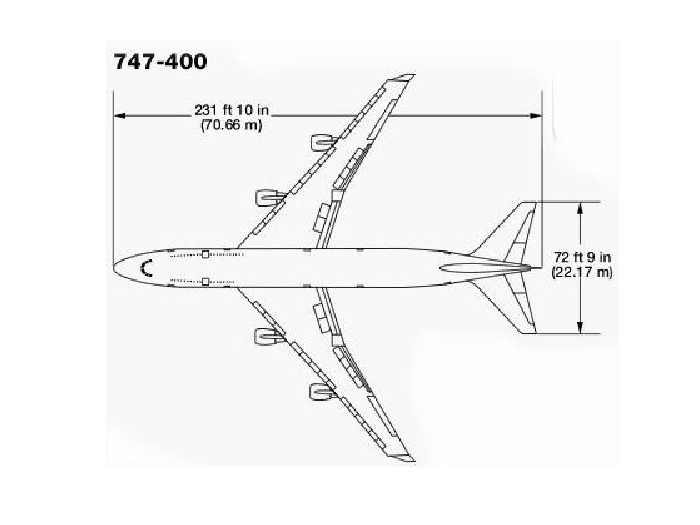

img = imread('747.jpg');
image(img)
axis image
axis off

## 2. Prompt user for 6 points

waitfor(msgbox({'Please select 6 points on the boundary of the wing';...
    'The sixth point does not need to coincide with the first point'}))

## 3. Select points

[x,y] = ginput(6);

Add colored rectangle to the image.

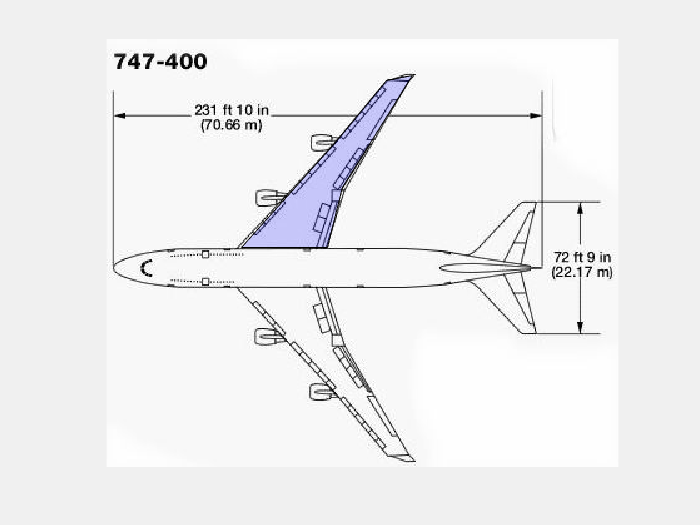

patch(x,y,'b','FaceAlpha',0.2)

## 4. Determine area in sq. pixels

pixarea = polyarea(x,y);

## 5. Convert area to sq. ft.

realarea = 2*pixarea/(1.466^2);

## 6. Report estimated wing area

disp(['Estimated wing area is: ',num2str(realarea), ' square feet']);

Estimated wing area is: 4586.5673 square feet
